# Optimization and Data Analytics HW16

## Introduction to Machine Learning Course Notes sec. 2

## Exercise 2.1

The exercise is to show that


$$\begin{array}{l}
W^\ast  \text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=\mathrm{arg}\text{ }\mathrm{min}\text{ }{\left\|W\overline{Y} -\overline{X} \right\|}_F^2 \\
\mathit{subject}\text{ }\mathit{to}\text{ }\text{ }\text{ }\text{ }\text{ }:W^T W=I
\end{array}$$


is equivalent to:


$$\begin{array}{l}
W^\ast  \text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=\arg \text{ }\mathrm{max}\text{ }\mathrm{Tr}\left(W^T \overline{X} {\overline{X} }^T W\right)\\
\text{subject}\text{ }\text{to}\text{ }\text{ }\text{ }\text{ }\text{ }:W^T W=I
\end{array}$$


Where *Tr* implies the trace of the matrix.and the data, *X*, is centered, so that:


$$X=X-{\mu 1}_N^T$$


Where $1_N \epsilon R^N$ is a vector of ones.

Given that $Y=W^T X$, the first optimization problem may be rewritten as:


$$\arg \text{ }\min \text{ }{\left\|W\overline{Y} -\overline{X} \right\|}_F^2 ={\left\|{\mathrm{WW}}^T \overline{X} -\overline{X} \right\|}_F^2$$


The ${\left\|\ldotp \right\|}_F^2$ is the squared *Forbenius *norm, which is given by:


$${\left\|A\right\|}_F^2 ={\left(\sqrt{\mathrm{Tr}\left({\mathrm{AA}}^T \right)}\right)}^{2\text{ }} =\mathrm{Tr}\left({\mathrm{AA}}^T \right)$$


The optimization problem may then be further rewritten to:


$$\begin{array}{l}
=\mathrm{Tr}\left({\left({\mathrm{WW}}^T \overline{X} -\overline{X} \right)}^T \left({\mathrm{WW}}^T \overline{X} -\overline{X} \right)\right)\\
=\mathrm{Tr}\left({\overline{X} }^T {\mathrm{WW}}^T {\mathrm{WW}}^T \overline{X} -2{\overline{X} }^T {\mathrm{WW}}^T \overline{X} +{\overline{X} }^T \overline{X} \right)\\
=\mathrm{Tr}\left({\overline{X} }^T \overline{X} -{\overline{X} }^T {\mathrm{WW}}^T \overline{X} \right)
\end{array}$$


The *trace* of ${\overline{X} }^T \overline{X}$ is a constant and the problem may therefore be rewritten as:


$$=\mathrm{const}\ldotp -\text{Tr}\left({\overline{X} }^T {\text{WW}}^T \overline{X} \right)$$


This is equivalent to:


$$=\text{const}\ldotp -\text{Tr}\left(W^T \overline{X} {\overline{X} }^T W\right)$$


Which corresponds to the second optimization problem. From these expression it is apparent that in order to minimize ${\left\|W\overline{Y} -\overline{X} \right\|}_F^2$, the expression $\text{Tr}\left(W^T \overline{X} {\overline{X} }^T W\right)$ should be maximized.

## Exercise 2.2

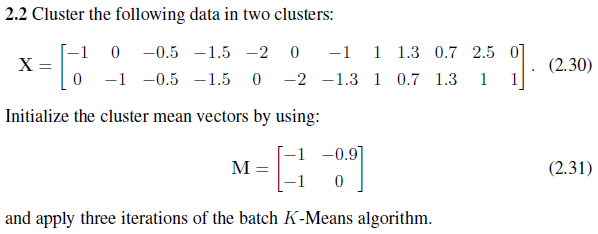

X = [-1 0 -0.5 -1.5 -2 0 -1 1 1.3 0.7 2.5 0;
    0 -1 -0.5 -1.5 0 -2 -1.3 1 0.7 1.3 1 1];
[m,n] = size(X);

M = [-1 -0.9;
    -1 0];
[m,K] = size(M);
iterations = 3;

The batch *K-means *algorithm is a method for classifying a set of samples *X* into K categories based on the distances of each sample from the mean of each category.

The initial mean vectors are given by **M**, and are used for the first iteration of the clustering algorithm. Each column vector in **M **is the mean of a class, which means there are two categorization classes in this exercise. Each row in the mean vectors represent the mean along one dimension.

In each iteration, the distances between each sample and the mean vector of each class is calculated by the euclidean norm of the difference between the sample vector and the mean vector (as no other norm is specified).


$$\mathrm{dist}=\left\|x_i -\mu_l \right\|=\sqrt{\sum_{k=1}^{N} {\left|{x_i }_k -{\mu_l }_k \right|}^2 }$$


Classification is then done by assigning each sample to class it has the minimum distance to.


$$l^\ast  =\mathrm{arg}\text{ }\mathrm{min}\left(\mathrm{dist}\right)$$


After classification, each class mean vector is updated to reflect any changes made in the assigned sample population:


$$\mu_k^\ast  =\frac{1}{N_k }\sum_{x_i \epsilon D_k } x_i$$


disp('K-means algorithm')
for i=1:iterations
    fprintf('Iteration: %d\n',i);
    % Classify samples based on distances to class mean
    distances = zeros(K,n);
    for j=1:n
        for k=1:K
            % Calculate distances to the mean class mean vectors
            distances(k,j) = norm(X(:,j)-M(:,k));           
        end 
    end
    disp('Distances:')
    distances
    
    % Label samples as class with lowest distance
    [val, idx] = min(distances);
    disp('Classification:')
    labels = idx
    
    % Calculate new class means
    for j=1:K
        [row,col] = find(labels == j);
        X_class = X(1:K,col);
        
        for k=1:m
            % Calculate class mean of each dimension
            M(k,j) = mean(X_class(k,:));          
        end
    end
    disp('Mean vectors:')
    M    
end

## Exercise 2.3

X = [-1 0 -0.5 -1.5 -2 0 -1 1 1.3 0.7 2.5 0;
    0 -1 -0.5 -1.5 0 -2 -1.3 1 0.7 1.3 1 1];
[m,n] = size(X);

M = [-1 -0.9;
    -1 0];
[m,K] = size(M);
iterations = 3;
gamma = 2;

The *fuzzy K-means algorithm* changes the membership assignment of the *K-means* *algorithm* to a membership vector, which is also dependent on the distance to the mean of each class. This vector defines "how much" a sample is a member of each class and is given by:


$$a_{\mathrm{ik}} =\frac{{\left\|x_i -\mu_k \right\|}^{-\gamma } }{\sum_{l=1}^{K} {\left\|x_i -\mu_l \right\|}^{-\gamma } }$$


The membership vector must add up to one, and therefore satisfy:


$$\sum_{k=1}^{K} a_{\mathrm{ik}} =1$$


After calculating the membership vector, the class means are updated by:


$$\mu_k =\sum_{i=1}^{N} a_{\mathrm{ik}} x_i ,\text{ }\text{ }\text{ }\text{ }k=1,\ldotp \ldotp \ldotp ,K$$


disp('Fuzzy K-means algorithm')

Fuzzy K-means algorithm


for i=1:iterations
    fprintf('Iteration: %d\n',i);
    
    % Classify samples based on distances to class mean
    distances = zeros(K,n);
    for j=1:n
        for k=1:K
            % Calculate distances to the mean class mean vectors
            distances(k,j) = norm(X(:,j)-M(:,k));                         
        end            
    end
    
    % Calculate membership values based on the euclidean distance and the fuzzification parameter gamma
    sum_of_distances_scaled = sum(distances.^(-gamma));    
    membership = zeros(K,n);
    for j=1:n
        for k=1:K
            membership(k,j) = distances(k,j)^(-gamma)/sum_of_distances_scaled(j);
        end          
    end
    
    disp('Distances:')
    distances
    
    disp('Membership values:')
    membership
    
    % Calculate new class means
    M = (membership*X')';   
    disp('Mean vectors:')
    M    
end

Iteration: 1


Distances:


distances =     1.0000    1.0000    0.7071    0.7071    1.4142    1.4142    0.3000    2.8284    2.8601    2.8601    4.0311    2.2361
    0.1000    1.3454    0.6403    1.6155    1.1000    2.1932    1.3038    2.1471    2.3087    2.0616    3.5440    1.3454


Membership values:


membership =     0.0099    0.6441    0.4505    0.8392    0.3769    0.7063    0.9497    0.3656    0.3945    0.3419    0.4360    0.2658
    0.9901    0.3559    0.5495    0.1608    0.6231    0.2937    0.0503    0.6344    0.6055    0.6581    0.5640    0.7342


Mean vectors:


M =    -0.9899    0.4899
   -2.9875    1.6875


Iteration: 2


Distances:


distances =     2.9875    2.2204    2.5353    1.5725    3.1537    1.3983    1.6876    4.4565    4.3407    4.6086    5.2991    4.1086
    2.2511    2.7318    2.4011    3.7577    3.0079    3.7199    3.3384    0.8561    1.2773    0.4408    2.1244    0.8442


Membership values:


membership =     0.3622    0.6022    0.4728    0.8510    0.4764    0.8762    0.7965    0.0356    0.0797    0.0091    0.1385    0.0405
    0.6378    0.3978    0.5272    0.1490    0.5236    0.1238    0.2035    0.9644    0.9203    0.9909    0.8615    0.9595


Mean vectors:


M =    -3.1325    2.6325
   -4.6207    3.3207


Iteration: 3


Distances:


distances =     5.0891    4.7877    4.8899    3.5220    4.7575    4.0842    3.9465    6.9764    6.9251    7.0529    7.9573    6.4347
    4.9216    5.0595    4.9407    6.3496    5.6998    5.9364    5.8776    2.8374    2.9400    2.7961    2.3245    3.5094


Membership values:


membership =     0.4833    0.5276    0.5052    0.7647    0.5894    0.6787    0.6893    0.1419    0.1527    0.1358    0.0786    0.2293
    0.5167    0.4724    0.4948    0.2353    0.4106    0.3213    0.3107    0.8581    0.8473    0.8642    0.9214    0.7707


Mean vectors:


M =    -3.1189    2.6189
   -3.4474    2.1474


## Exercise 2.4

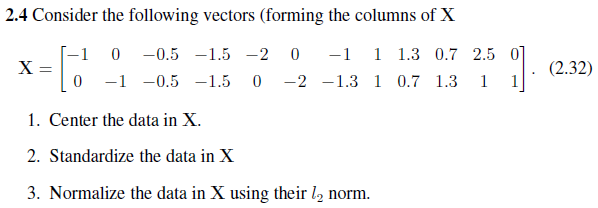

X = [-1 0 -0.5 -1.5 -2 0 -1 1 1.3 0.7 2.5 0;
    0 -1 -0.5 -1.5 0 -2 -1.3 1 0.7 1.3 1 1];
[m,n] = size(X);

## 1) Centering

Centering is given by:


$$\overline{x_i } =x_i -\mu ,\text{  }i=1,\ldotp \ldotp \ldotp ,N$$


Where the mean vector $\mu \text{ }\epsilon \text{ }R^D$ is given by:


$$\mu =\frac{1}{N}\sum_{i=1}^{N} x_i$$


% Calculate the mean vector
mean_vector = mean(X,2)

% Center data
X_centered = X-mean_vector

## 2) Standardizing

Data standardization applies both centering and scaling of each dimension of the data.

The vector *s* is formed by the standard deviation values of each dimension of the data:


$$s_d =\frac{1}{N-1}\sqrt{\sum_{i=1}^{N} {\left(x_{\mathrm{id}} -\mu_d \right)}^2 }$$


The data is then standardized by:


$$\hat{x_{\mathrm{id}} } =\frac{x_{\mathrm{id}} -\mu_d }{s_d }$$


% Calculate standard deviation
s = std(X,0,2)

% Standardize data
X_standardized = (X-mean_vector)./s

## 3) Normalizing

Data normalization scales each sample independently, so that it satisfies a criterion.

$l_2$ normalization scales the values of a vector as follows:


$$\tilde{x_i } =\frac{x_i }{\left\|x_i \right\|}=\frac{x_i }{\sqrt{x_i^T x_i }}$$


X_norm = X./sqrt(sum(abs(X).^2))

## Exercise 2.5

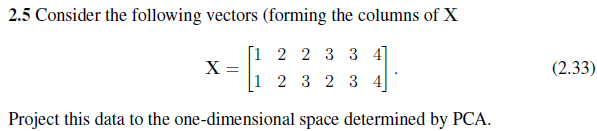

X = [1 2 2 3 3 4;
    1 2 3 2 3 4];

In order to project the data, it is necessary to determine the covariance matrix, which is given by:


$$S_T =\overline{X} \overline{X^T }$$


Where $\overline{X}$is the centered data matrix.

By applying an eigen-analysis to the covariance matrix $S_T$ the eigenvalues and eigenvectors may be found.

The projected data may then be determined by:


$$x_{\mathrm{proj}} =v^T X$$


Where *v *is the eigenvector of the maximum eigenvalue of the covariance matrix $S_T$.

% Calculate the mean vector
mean_vector = mean(X,2)

mean_vector =     2.5000
    2.5000



% Center data
X_cent = X-mean_vector

X_cent =    -1.5000   -0.5000   -0.5000    0.5000    0.5000    1.5000
   -1.5000   -0.5000    0.5000   -0.5000    0.5000    1.5000



% Determine covariance matrix
S_T = X_cent*X_cent'

S_T =     5.5000    4.5000
    4.5000    5.5000



% Determine maximum eigenvalue and corresponding eigenvector of the covariance matrix
[v, d] = eigs(S_T,1)

v =     0.7071
    0.7071


d = 10


% Project data
x = v'*X

x =     1.4142    2.8284    3.5355    3.5355    4.2426    5.6569


Plotting the points and the principal axis:

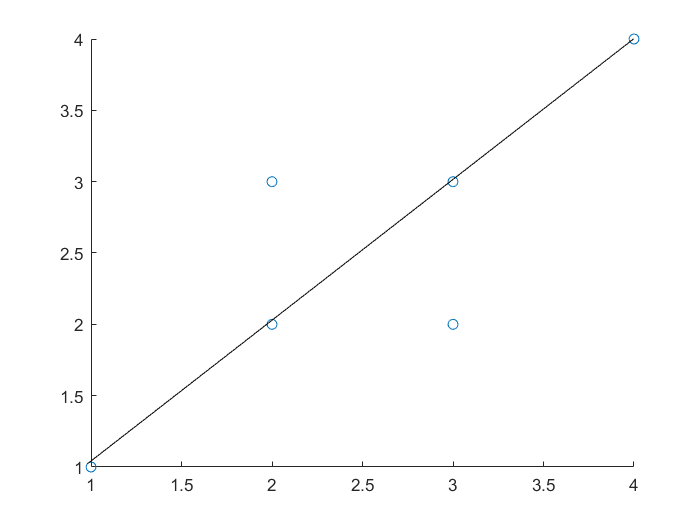

figure
scatter(X(1,:),X(2,:))
annotation('line',[0.125 0.9054],[0.1167 0.9262])